bag = rosbag('joint_torque_2.bag')

bag =   BagSelection with properties:

           FilePath: 'C:\Users\ANDREA\Downloads\joint_torque_2.bag'
          StartTime: 0.4100
            EndTime: 2.9100
        NumMessages: 3514
    AvailableTopics: [7×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3514×4 table]


bagInfo = rosbag('info','joint_torque_2.bag')

bagInfo = struct with fields:
        Path: 'C:\Users\ANDREA\Downloads\joint_torque_2.bag'
     Version: '2.0'
    Duration: 2.5000
       Start: [1×1 struct]
         End: [1×1 struct]
        Size: 240685
    Messages: 3514
       Types: [1×1 struct]
      Topics: [7×1 struct]


rosbag info 'joint_torque_2.bag'

Path:     C:\Users\ANDREA\Downloads\joint_torque_2.bag
Version:  2.0
Duration: 2.5s
Start:    gen 01 1970 01:00:00.41 (0.41)
End:      gen 01 1970 01:00:02.91 (2.91)
Size:     235.0 KB
Messages: 3514
Types:    std_msgs/Float64 [fdb28210bfa9d7c91146260178d9a584]
Topics:   /iiwa/iiwa_joint_1_effort_controller/command  502 msgs  : std_msgs/Float64
          /iiwa/iiwa_joint_2_effort_controller/command  502 msgs  : std_msgs/Float64
          /iiwa/iiwa_joint_3_effort_controller/command  502 msgs  : std_msgs/Float64
          /iiwa/iiwa_joint_4_effort_controller/command  502 msgs  : std_msgs/Float64
          /iiwa/iiwa_joint_5_effort_controller/command  502 msgs  : std_msgs/Float64
          /iiwa/iiwa_joint_6_effort_controller/command  502 msgs  : std_msgs/Float64
          /iiwa/iiwa_joint_7_effort_controller/command  502 msgs  : std_msgs/Float64



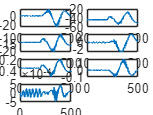

X = 0.1700


jt_1 = select(bag,'Topic','iiwa/iiwa_joint_1_effort_controller/command');
msgStructs = readMessages(jt_1,'DataFormat','struct');
jt_1_double = cellfun(@(m) double(m.Data),msgStructs);
jt_2 = select(bag,'Topic','iiwa/iiwa_joint_2_effort_controller/command');
msgStructs = readMessages(jt_2,'DataFormat','struct');
jt_2_double = cellfun(@(m) double(m.Data),msgStructs);
jt_3 = select(bag,'Topic','iiwa/iiwa_joint_3_effort_controller/command');
msgStructs = readMessages(jt_3,'DataFormat','struct');
jt_3_double = cellfun(@(m) double(m.Data),msgStructs);
jt_4 = select(bag,'Topic','iiwa/iiwa_joint_4_effort_controller/command');
msgStructs = readMessages(jt_4,'DataFormat','struct');
jt_4_double = cellfun(@(m) double(m.Data),msgStructs);
jt_5 = select(bag,'Topic','iiwa/iiwa_joint_5_effort_controller/command');
msgStructs = readMessages(jt_5,'DataFormat','struct');
jt_5_double = cellfun(@(m) double(m.Data),msgStructs);
jt_6 = select(bag,'Topic','iiwa/iiwa_joint_6_effort_controller/command');
msgStructs = readMessages(jt_6,'DataFormat','struct');
jt_6_double = cellfun(@(m) double(m.Data),msgStructs);
jt_7 = select(bag,'Topic','iiwa/iiwa_joint_7_effort_controller/command');
msgStructs = readMessages(jt_7,'DataFormat','struct');
jt_7_double = cellfun(@(m) double(m.Data),msgStructs);

subplot (4,2,1)
plot(jt_1_double)
subplot (4,2,2)
plot(jt_2_double)
subplot (4,2,3)
plot(jt_3_double)
subplot (4,2,4)
plot(jt_4_double)
subplot (4,2,5)
plot(jt_5_double)
subplot (4,2,6)
plot(jt_6_double)
subplot (4,2,7)
plot(jt_7_double)